% 创建并训练随机森林模型
numTrees = 100;  % 设置决策树的数量
Bagging = TreeBagger(numTrees, train_X, train_y, 'Method', 'classification');

% 使用训练好的模型进行预测
predicted_labels = predict(Bagging, test_X);
predicted_labels_train = predict(Bagging, train_X);

prediction_train = zeros(numel(train_y, 1));
for i = 1:numel(train_y)
%     prediction_train(i) = predicted_labels_train{i} - '0';
    prediction_train(i) = str2num(predicted_labels_train{i});
end

prediction = zeros(numel(test_y, 1));
for i = 1:numel(test_y)
    prediction(i) = str2num(predicted_labels{i});
end
accuracy = sum(prediction' == test_y) / size(test_y, 1)

accuracy = 1

accuracy_train = sum(prediction_train' == train_y) / size(train_y, 1)

accuracy_train = 1

% 准确率100%

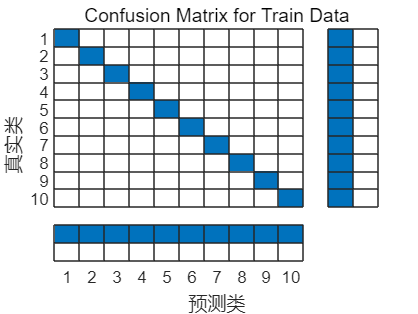

% 混淆矩阵
figure
cm = confusionchart(prediction_train, train_y);
cm.Title = 'Confusion Matrix for Train Data';
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';

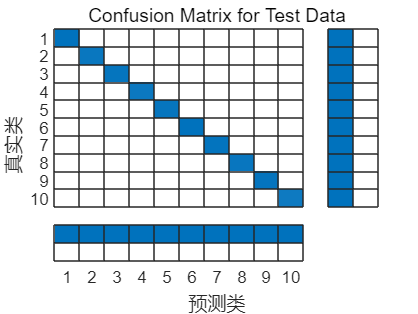

    
figure
cm = confusionchart(prediction, test_y);
cm.Title = 'Confusion Matrix for Test Data';
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';